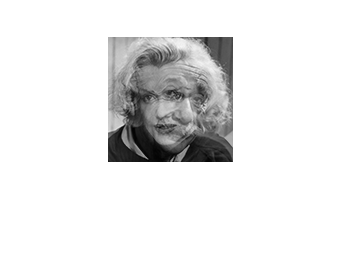

% Thomas Monfre
% SA5 Practice Study for Exam

clear;
load('S5Images.mat');
addpath(['cs11lib']);

display_image(M1);

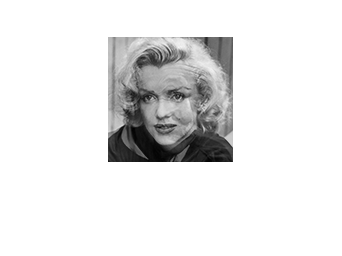

display_image(M2);

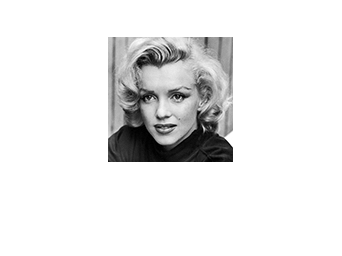


S1 = zeros(125,125);
S2 = zeros(125,125);

M = [0.45 0.55 ; 0.65 0.35];
invM = inv(M);

for k=1 : length(M1)
    for q=1 : length(M2)
        
        u = invM * [M1(k,q) ; M2(k,q)];
        
        S1(k,q) = u(1,1);
        S2(k,q) = u(2,1);
        
    end
end

display_image(S1);

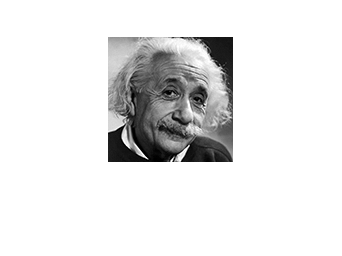

display_image(S2);

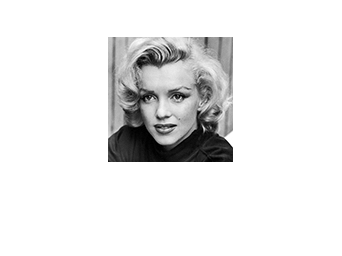


clear;
load(['S5Images.mat']);

M = [0.45 0.55 ; 0.65 0.35];
invM = inv(M);

M1v = M1(:)';
M2v = M2(:)';

v = [M1v ; M2v];

u = invM * v;

S1 = reshape(u(1,:), [125,125]);
S2 = reshape(u(2,:), [125,125]);

display_image(S1);

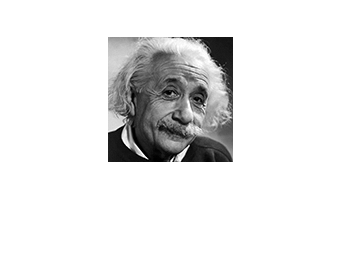

display_image(S2);